# Plot M3C Variables

buffer

buffer =   ClassBuffer with properties:

                 Ts: 1.0000e-04
                 Ns: 2500
                  m: 9
                  n: 4
                  A: [6×9 double]
               Tsim: [0 1.0004e-04 2.0008e-04 3.0012e-04 4.0016e-04 5.0020e-04 6.0024e-04 7.0028e-04 8.0032e-04 9.0036e-04 0.0010 0.0011 0.0012 0.0013 0.0014 0.0015 0.0016 0.0017 0.0018 0.0019 0.0020 0.0021 0.0022 0.0023 0.0024 0.0025 … ] (1×2500 double)
                 is: [9×2500 double]
                ixy: [6×2500 double]
                 iB: [9×2500 double]
                 iz: [9×2500 double]
                 ie: [4×2500 double]
                 vs: [9×2500 double]
                vxy: [6×2500 double]
                 vB: [9×2500 double]
                 vo: [0 -0.0048 0.0026 0.0152 0.0344 0.0621 0.0997 0.1475 0.2052 0.2719 0.3459 0.4245 0.5046 0.5825 0.6538 0.7135 0.7564 0.7770 0.7696 0.7285 0.6479 0.5226 0.3474 0.1178 -0.1700 -0.51

Tsim = buffer.Tsim;
clf

## `vxy`

% % abc
% 
% figure
% subplot(2, 1, 1)
% hold on
% stairs(Tsim, buffer.vxy(1:3, :)')
% hold off
% legend('vxa', 'vxb', 'vxc')
% ylabel('Input Voltage (V)')
% grid on
% 
% subplot(2, 1, 2)
% stairs(Tsim, buffer.vxy(4:6, :)')
% legend('vyr', 'vys', 'vyt')
% ylabel('Output Voltage (V)')
% grid on
% xlabel('Time (s)')
% 
% % dq
% 
% figure
% subplot(2, 1, 1)
% stairs(Tsim, buffer.vxdq')
% legend('vxd', 'vxq')
% ylabel('Input Voltage (V)')
% grid on
% 
% subplot(2, 1, 2)
% stairs(Tsim, buffer.vydq')
% legend('vyd', 'vyq')
% ylabel('Output Voltage (V)')
% grid on
% 
% xlabel('Time (s)')

## Input PLL

% figure
% 
% % Estimations
% subplot(2, 1, 1)
% 
% % Angle
% stairs(Tsim, buffer.gx')
% hold on
% stairs(Tsim, buffer.gx_pll', '--')
% hold off
% ylabel('Input Angle (rad)')
% 
% % Frequency
% yyaxis right
% stairs(Tsim, buffer.wx')
% hold on
% stairs(Tsim, buffer.wx_pll', '--')
% hold off
% ylabel('Input Frequency (rad/s)')
% 
% % Performance
% subplot(2, 1, 2)
% 
% % Error
% stairs(Tsim, buffer.ex_pll')
% ylabel('Error')
% 
% % Control action
% yyaxis right
% stairs(Tsim, buffer.ux_pll')
% ylabel('Control action')
% 
% xlabel('Time (s)')
% grid on

## Output PLL

% figure
% 
% % Estimations
% subplot(2, 1, 1)
% 
% % Angle
% stairs(Tsim, buffer.gy')
% hold on
% stairs(Tsim, buffer.gy_pll', '--')
% hold off
% ylabel('Output Angle (rad)')
% 
% % Frequency
% yyaxis right
% stairs(Tsim, buffer.wy')
% hold on
% stairs(Tsim, buffer.wy_pll', '--')
% hold off
% ylabel('Output Frequency (rad/s)')
% 
% % Performance
% subplot(2, 1, 2)
% 
% % Error
% stairs(Tsim, buffer.ey_pll')
% ylabel('Error')
% 
% % Control action
% yyaxis right
% stairs(Tsim, buffer.uy_pll')
% ylabel('Control action')
% 
% xlabel('Time (s)')
% grid on

## `vB`

% figure
% stairs(Tsim, buffer.vB')
% xlabel('Time (s)')
% ylabel('Basic Voltage (V)')
% grid on

## `vs`

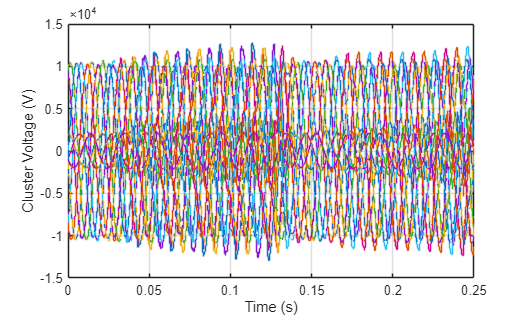

figure
stairs(Tsim, buffer.vs')
hold on
stairs(Tsim, buffer.vs_ref', '--')
hold off
xlabel('Time (s)')
ylabel('Cluster Voltage (V)')
grid on

## is

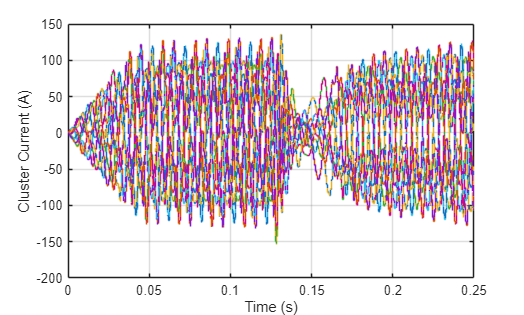

figure
stairs(Tsim, buffer.is')
hold on
stairs(Tsim, buffer.is_ref', '--')
hold off
xlabel('Time (s)')
ylabel('Cluster Current (A)')
grid on

## ixy

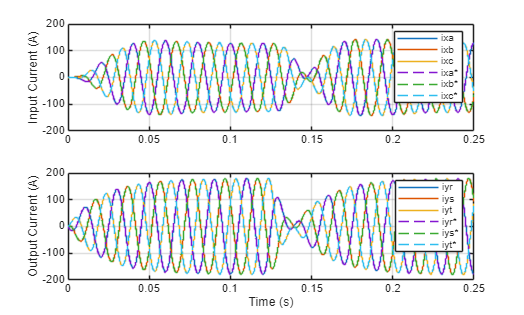

% abc

figure
subplot(2, 1, 1)
stairs(Tsim, buffer.ixy(1:3, :)')
hold on
stairs(Tsim, buffer.ixy_ref(1:3, :)', '--')
hold off
legend('ixa', 'ixb', 'ixc', 'ixa*', 'ixb*', 'ixc*')
ylabel('Input Current (A)')
grid on

subplot(2, 1, 2)
stairs(Tsim, buffer.ixy(4:6, :)')
hold on
stairs(Tsim, buffer.ixy_ref(4:6, :)', '--')
hold off
legend('iyr', 'iys', 'iyt', 'iyr*', 'iys*', 'iyt*')
ylabel('Output Current (A)')
grid on
xlabel('Time (s)')

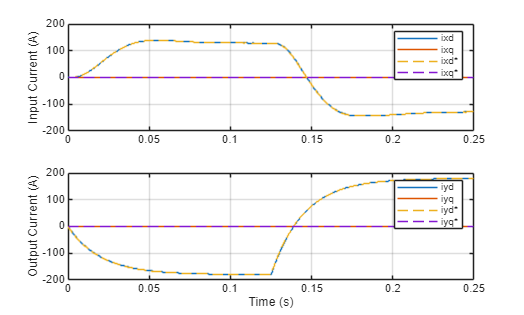


% dq

figure
subplot(2, 1, 1)
stairs(Tsim, buffer.ixdq')
hold on
stairs(Tsim, buffer.ixdq_ref', '--')
hold off
legend('ixd', 'ixq', 'ixd*', 'ixq*')
ylabel('Input Current (A)')
grid on

subplot(2, 1, 2)
stairs(Tsim, buffer.iydq')
hold on
stairs(Tsim, buffer.iydq_ref', '--')
hold off
legend('iyd', 'iyq', 'iyd*', 'iyq*')
ylabel('Output Current (A)')
grid on

xlabel('Time (s)')

## `iB`

% figure
% stairs(Tsim, buffer.iB')
% hold on
% stairs(Tsim, buffer.iB_ref', '--')
% hold off
% xlabel('Time (s)')
% ylabel('Basic Current (A)')
% grid on

## `iz`

% figure
% stairs(Tsim, buffer.iz')
% hold on
% stairs(Tsim, buffer.iz_ref', '--')
% hold off
% xlabel('Time (s)')
% ylabel('Circulating Current (A)')
% grid on

## `Ec`

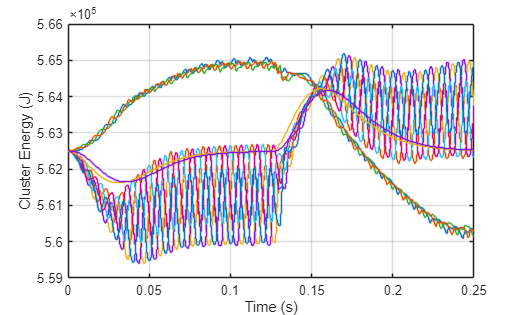

figure
stairs(Tsim, buffer.Ec')
hold on
stairs(Tsim, buffer.Ec_mean')
stairs(Tsim, buffer.Ec_mean_filt')
hold off
ylabel('Cluster Energy (J)')
xlabel('Time (s)')
grid on

## TEB PI

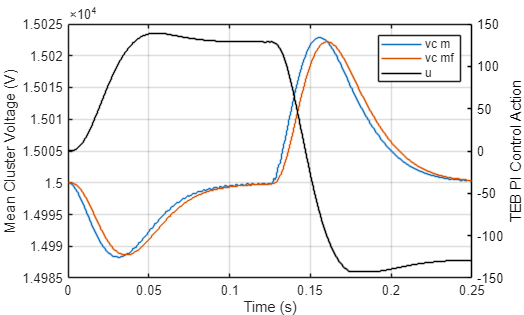

figure

stairs(Tsim, buffer.vc_mean')
hold on
stairs(Tsim, buffer.vc_mean_filt')
hold off
ylabel('Mean Cluster Voltage (V)')

yyaxis right
stairs(Tsim, buffer.u_TEB', 'Color', 'black')
ylabel('TEB PI Control Action')
ax = gca;
ax.YAxis(2).Color = 'black';
ax.YColor = 'black';

legend('vc m', 'vc mf', 'u')
xlabel('Time (s)')
grid on

## `vc`

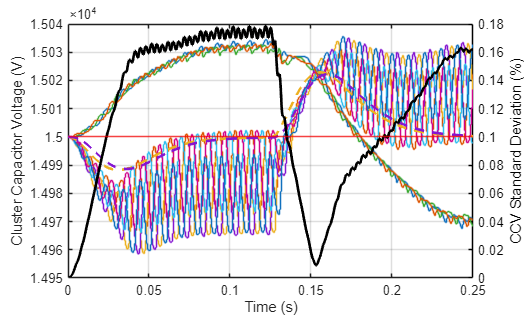

figure

stairs(Tsim, buffer.vc')
hold on
stairs(Tsim, buffer.vc_mean', '--', 'LineWidth', 2)
stairs(Tsim, buffer.vc_mean_filt', '--', 'LineWidth', 2)
yline(buffer.vc_mean(1), 'Color', 'red')
hold off
ylabel('Cluster Capacitor Voltage (V)')

yyaxis right
stairs(Tsim, 100*std(buffer.vc./buffer.vc_mean)', 'LineWidth', 2, 'Color', 'black')
ylabel('CCV Standard Deviation (%)')
ax = gca;
ax.YAxis(2).Color = 'black';
ax.YColor = 'black';

xlabel('Time (s)')
grid on

## `ie`

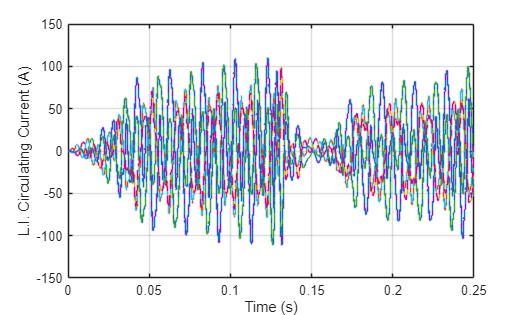

figure
stairs(Tsim, buffer.ie')
hold on
stairs(Tsim, buffer.ie_ref', '--')
hold off
xlabel('Time (s)')
ylabel('L.I. Circulating Current (A)')
grid on

## `vo`

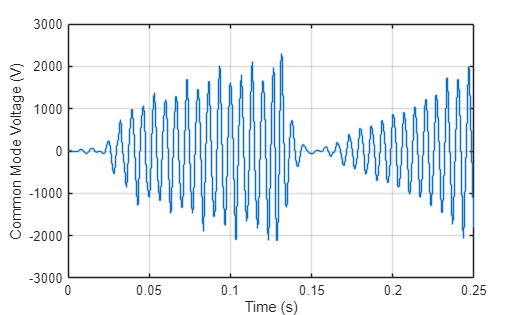

figure
stairs(Tsim, buffer.vo')
xlabel('Time (s)')
ylabel('Common Mode Voltage (V)')
grid on

## Exit Flags

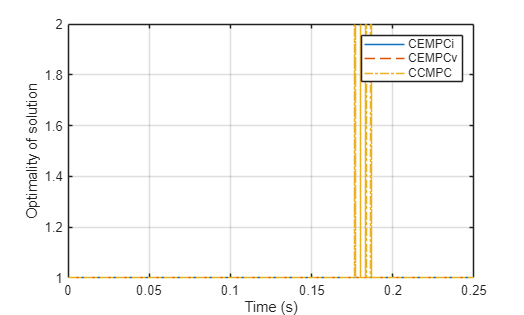

figure
stairs(Tsim, buffer.exitflag_CEMPCi', '-')
hold on
stairs(Tsim, buffer.exitflag_CEMPCv', '--')
stairs(Tsim, buffer.exitflag_CCMPC', '-.')
hold off
ylabel('Optimality of solution')
xlabel('Time (s)')
legend('CEMPCi', 'CEMPCv', 'CCMPC')
grid on

## Active Constraints

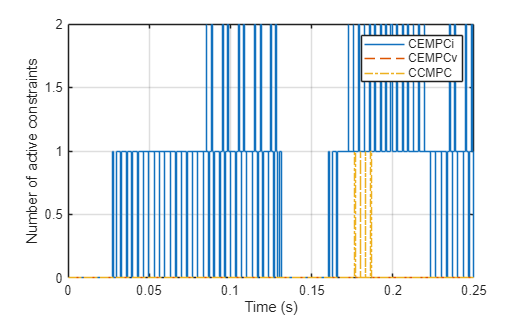

figure
stairs(Tsim, buffer.iA_CEMPCi', '-')
hold on
stairs(Tsim, buffer.iA_CEMPCv', '--')
stairs(Tsim, buffer.iA_CCMPC', '-.')
hold off
ylabel('Number of active constraints')
xlabel('Time (s)')
legend('CEMPCi', 'CEMPCv', 'CCMPC')
grid on

## Controller Execution Time

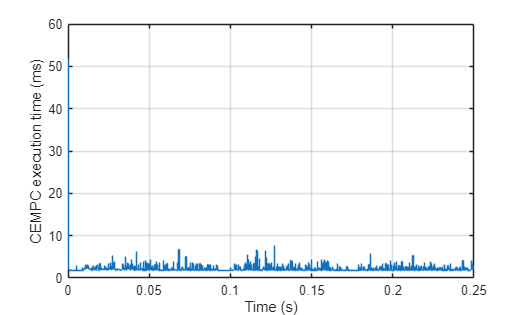

figure
stairs(Tsim, buffer.Tex_CEMPC'*1000)
ylabel('CEMPC execution time (ms)')
xlabel('Time (s)')
grid on

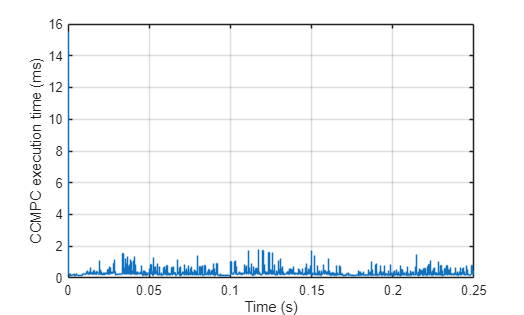


figure
stairs(Tsim, buffer.Tex_CCMPC'*1000)
ylabel('CCMPC execution time (ms)')
xlabel('Time (s)')
grid on